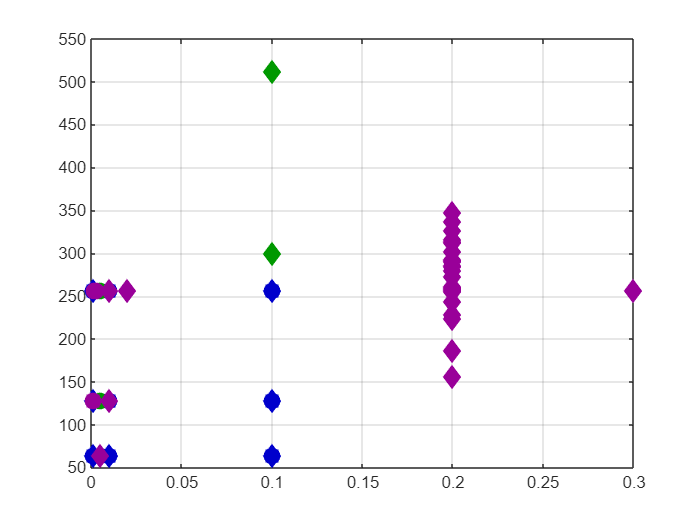

Error using indexing
The specified key is not present in this container.

% Read Excel sheet
data = readtable('experiment_summary.xlsx');

learningRate = data.LearningRate;
batchSize = data.BatchSize;
accuracy = data.Accuracy;
convBlocks = data.ConvBlocks;
method = data.Method;

optimizerTypes = unique(method);
convUnique = unique(convBlocks);

% Map marker shapes for optimizers
markers = {'o', 's', 'd'}; % adjust if more optimizers
markerMap = containers.Map(optimizerTypes, markers);

% Darker, strong colors
colors = [...
    0.8 0 0;    % dark red
    0 0.6 0;    % dark green
    0 0 0.8;    % dark blue
    0.6 0 0.6;  % dark magenta
    0 0.6 0.6;  % dark cyan
    0.8 0.4 0;  % dark orange
    0.4 0 0.4;  % dark purple
];

% Map colors to conv blocks
colorMap = containers.Map(convUnique, num2cell(colors(1:length(convUnique), :), 2));


% Map colors to conv blocks
colorMap = containers.Map(convUnique, num2cell(colors(1:length(convUnique), :), 2));


% Map conv blocks to descriptive labels
convLabelsMap = containers.Map(...
    [2, 3, 4, 5], ...
    {'2 blocks', '3 blocks', '4 blocks', '4 blocks + Dense'});

figure;
hold on;
grid on;
box on;
legendHandles = [];
legendLabels = {};

% Plot each unique combination once
for o = 1:length(optimizerTypes)
    for c = 1:length(convUnique)
        idx = strcmp(method, optimizerTypes{o}) & convBlocks == convUnique(c);
        if any(idx)
            x = learningRate(idx);
            y = batchSize(idx);
            z = accuracy(idx);
            
            h = scatter3(x, y, z, 100, colorMap(convUnique(c)), markerMap(optimizerTypes{o}), 'filled');
            
            legendHandles(end+1) = h; %#ok<SAGROW>
            legendLabels{end+1} = [optimizerTypes{o} ', ' convLabelsMap(convUnique(c))]; %#ok<SAGROW>
        end
    end
end


xlabel('Learning Rate(log)');
ylabel('Batch Size(log)');
zlabel('Accuracy(%)');
set(gca, 'XScale', 'log', 'YScale', 'log');
grid on;
xlim([1e-4 1])      % example limits for learning rate
ylim([0 300])      % example limits for batch size
zlim([0 100])       % example limits for accuracy


% Example: highlight a specific point
[~, highlightIdx] = max(accuracy);  % returns index of max accuracy;  % index of the row you want to highlight

x_high = learningRate(highlightIdx);
y_high = batchSize(highlightIdx);
z_high = accuracy(highlightIdx);

h_high = scatter3(x_high, y_high, z_high, 300, 'r', 'o'); % bigger, red, pentagram

legend(legendHandles, legendLabels, 'Location', 'southwest');

hold off;

view([43.2 12.6])

batchSlices = [64, 128, 256];
t = tiledlayout(1, length(batchSlices), 'TileSpacing', 'compact', 'Padding', 'compact');

legendHandles = [];
legendLabels = {};

for i = 1:length(batchSlices)
    ax = nexttile;

    idx = batchSize == batchSlices(i);
    x = learningRate(idx);
    z = accuracy(idx);
    m = method(idx);
    c = convBlocks(idx);

    hold(ax, 'on');
    xlim([5e-4 0.5])      
    ylim([0 100])   
    % Plot actual points
    for j = 1:length(x)
        scatter(ax, x(j), z(j), 40, colorMap(c(j)), markerMap(m{j}), 'filled');
    end
    
    xlabel(ax, 'Learning Rate');
    ylabel(ax, 'Accuracy');
    set(ax, 'XScale', 'log');
    title(ax, ['Batch Size = ' num2str(batchSlices(i))]);
    grid(ax, 'on');
    hold(ax, 'off');
end
   

% Create dummy points for legend on the first axes
ax1 = nexttile(1); % first tile
hold(ax1, 'on');

for o = 1:length(optimizerTypes)
    for cb = 1:length(convUnique)
        h = scatter(ax1, nan, nan, 100, colorMap(convUnique(cb)), markerMap(optimizerTypes{o}), 'filled');
        legendHandles(end+1) = h;
        legendLabels{end+1} = [optimizerTypes{o} ', ' convLabelsMap(convUnique(cb))];
    end
end
theme("light"); % Set the figure theme to light

legend(ax1, legendHandles, legendLabels, 'Location', 'southwest');


